clear all, close all, clf
%icke-linjärt sys med Newtons
%Lab2-G-H
x_start=[1,1,1];
%koordinater
x1=10;
x2=12;
x3=3;
y1=10;
y2=2;
y3=8;
xp=[x1,x2,x3];
yp=[y1,y2,y3];
solutions = zeros(2,3);
c=zeros(3,2);
k1 = [1,3];
A=[ones(3,1),xp',yp'];%uppgift g
b=[x1^2+y1^2;x2^2+y2^2;x3^2+y3^2];
R_funk= @(c1,c2,c3) ((c3)^2)/4+((c2)^2)/4+c1;
for k=1:2
    A(3,:) = A(3,:)*k1(k);
    b(3) = b(3)*k1(k);
    c(:,k)=A\b;%uppgift g
    c1=c(1,k);
    c2=c(2,k);
    c3=c(3,k);
    R1 = R_funk(c1,c2,c3);
    solutions(k,:)=[c2/2,c3/2,sqrt(R1)];
end


teta = linspace(0,2*pi);
R = solutions(1,:);
x11 = R(1) + R(3)*cos(teta);
y11 = R(2) + R(3)*sin(teta);
R2 = solutions(2,:);
x22 = R2(1) + R2(3)*cos(teta);
y22 = R2(2) + R2(3)*sin(teta);
ML=ones(4);
ML(4,:) = 3*ML(4,:);

plot(xp,yp,'*')
hold on
plot(x11,y11,'r')
plot(R(1),R(2),'o-g')
plot(x22,y22,'--b')
axis equal
xlabel('x');
ylabel('y');
title('Plot av koordinater samt lösning till cirkel')
fprintf('X=%.5f\n',R(1));

X=7.60000


fprintf('Y=%.5f\n',R(2));

Y=5.15000


fprintf('R=%.5f\n',R(3));

R=5.41133


fprintf('X=%.5f\n',R2(1));

X=7.60000


fprintf('Y=%.5f\n',R2(2));

Y=5.15000


fprintf('R=%.5f\n',R2(3));

R=5.41133


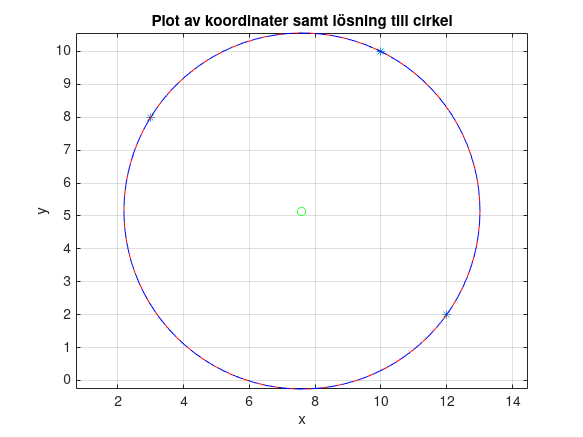

grid on